# Vòng lặp

[Menu menu chính](matlab:open('MainMenu.mlx'))

Máy tính phải được nói rõ ràng làm thế nào để đưa ra quyết định. Một loại quyết định phổ biến trong lập trình máy tính liên quan đến việc lặp lại, đó là liệu có nên lặp lại một phần mã hay không. Mã vòng lặp thường có mặt khi tính toán tương tự sẽ được áp dụng cho các dữ liệu khác nhau mỗi lần hoặc khi đầu ra từ vòng lặp được cung cấp lại làm đầu vào cho mã vòng lặp cho lần lặp tiếp theo. Kịch bản này sẽ trình bày hai loại hướng dẫn lặp khác nhau: vòng lặp `for `và vòng lặp `while`. Bạn nghĩ loại vòng lặp nào được hiển thị ở đây?

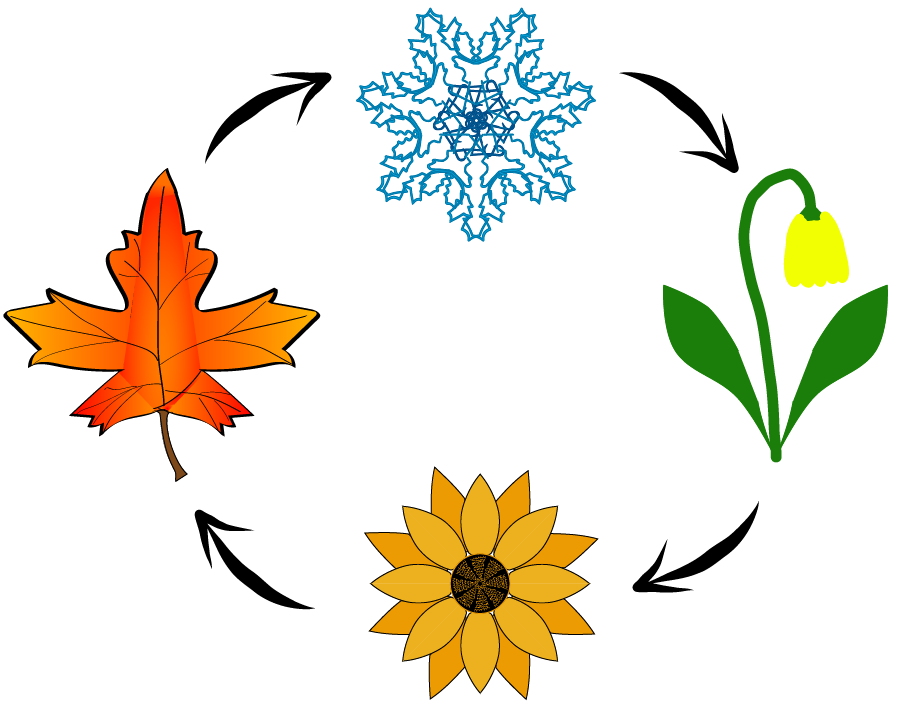

Các vòng lặp là một trong những phương pháp tiết kiệm thời gian quan trọng nhất trong lập trình vì bạn chỉ cần viết các hướng dẫn một lần nhưng máy tính có thể chạy các hướng dẫn nhiều lần.

**Trước khi bạn bắt đầu:**

Tập lệnh trực tiếp này được dự định sẽ được sử dụng với mã hiển thị và đầu ra nội tuyến. TRÊN  **View** tab của công cụ MATLAB, trong **View** section, chọn **Output Inline**. Thay phiên, chọn **Output inline **Sử dụng biểu tượng   Ở phía trên bên phải của Live Editor pane.

 Tương tác với tập lệnh trực tiếp này sẽ xây dựng một số quen thuộc với MATLAB, vì các khái niệm và lệnh được giới thiệu cùng nhau, nhưng một số quen thuộc với môi trường biên tập trực tiếp đã được giới thiệu trong[Giới thiệu.MLX](matlab:open('./Introduction.mlx')). Một bản tóm tắt ngắn gọn về các công cụ, mẹo và đề xuất từ ��mỗi tập lệnh được thu thập[Thu thập các mẹo chuyên nghiệp](matlab:open('./CollectedProTips.mlx'))

  Để có trải nghiệm tối ưu, hãy làm theo các hướng dẫn và các bước trong chuỗi đã cho. Chỉ tiến hành một phần mới sau khi hoàn thành phần trước, bao gồm cả chạy tất cả các khối mã.

## Vòng lặp

Hai loại vòng lặp phổ biến nhất là vòng lặp `for` và vòng lặp `while`. Mặc dù không phải lúc nào cũng đúng với lập trình, nhưng các tên ở đây cho bạn một dấu hiệu khá rõ ràng về cách chúng hoạt động từ ý nghĩa hàng ngày của các từ.

### Vòng lặp For

Vòng lặp `for` là một phần mã được phân tách rõ ràng sẽ chạy một số lần đã đặt, theo chỉ dẫn của lập trình viên.. 

Số lượng lặp lại có thể được đặt trực tiếp, ví dụ: bằng cách đặt tên một giá trị chỉ mục như`k`và sau đó cung cấp giá trị bắt đầu và kết thúc. Chạy khối mã để quan sát giá trị thay đổi của chỉ mục mỗi khi thân của vòng lặp chạy.

for k = 1:10
    str = "The current value of the loop index is " + k
end

Thay phiên, bạn có thể xác định một chỉ mục vòng lặp theo bất kỳ vectơ giá trị nào khác. Nếu bạn bắt đầu với vectơ  `ngày `1x7 Điều đó chứa một chuỗi cho mỗi ngày trong tuần, vòng lặp sẽ thực thi mã cơ thể với chỉ mục được đặt thành từng phần tử vectơ lần lượt. Chạy khối mã bên dưới để quan sát giá trị thay đổi của chỉ mục mỗi khi thân của vòng lặp chạy.

DaysOfWeek = ["Monday" "Tuesday" "Wednesday" "Thursday" "Friday" "Saturday" "Sunday"];

Invalid text character. Check for unsupported symbol, invisible character, or pasting of non-ASCII characters.

for d = DaysOfWeek
    str = "Today is " + d + ", tomorrow is another day."
end

Hình thức sau đôi khi được gọi là`ForEach`Vòng lặp, bởi vì nó thực thi cho từng phần tử của bộ lập chỉ mục.

Một số ngôn ngữ lập trình yêu cầu lập trình viên cập nhật rõ ràng giá trị chỉ mục trong vòng lặp trong khi các ngôn ngữ khác, chẳng hạn như MATLAB, sẽ tự động cập nhật giá trị chỉ mục cho mỗi lần lặp.

#### **Bài tập 1.**

Viết Vòng lặp `for` sẽ in ra bình phương của 25 số nguyên dương đầu tiên.

% Viết mã của bạn ở đây. Thay thế nhận xét này bằng một bình luận thích hợp hơn.
% Bạn có thể so sánh các giá trị của mình với 25 hình vuông đầu tiên được đưa ra là
% First25Squares trong phần Giải pháp tham chiếu

#### **Bài tập 2.**

Viết Vòng lặp `for` sẽ kể ít nhất ba trò đùa "gõ gõ". Những trò đùa được bao gồm trong Giải pháp tham khảo Phần để bạn biết những gì bạn đang nhắm đến để tái tạo. Nếu bạn muốn viết thêm những trò đùa "gõ gõ", hãy cảm thấy tự do (đánh gục mình). Nếu bạn cần đánh giá [Kết hợp chuỗi](matlab:open('./Data.mlx')) hoặc [lập chỉ mục vector](matlab:open('./Arrays.mlx')), bạn có thể xem lại tập lệnh có liên quan hoặc tham khảo [Thu thập các mẹo chuyên nghiệp](matlab:open('./CollectedProTips.mlx')) Bộ sưu tập tham khảo.

Opening = "Knock Knock!" + newline + "Who's there?";
Answer = ["Orange" "Who" "Boo"];
Punchline = ["Orange you glad I didn't say banana?" "I didn't know you were an owl!" "Please don't cry!"];


### Vòng lặp While

MỘT Vòng lặp `while` bắt đầu mỗi lần thực hiện bằng cách hỏi một câu hỏi. Nếu câu hỏi đó đánh giá là boolean `ĐÚNG`, sau đó mã trong Vòng lặp `while` sẽ chạy. Nếu câu hỏi đó đánh giá là boolean `SAI`, sau đó vòng lặp chấm dứt. Hãy cẩn thận, bởi vì lệnh này có thể làm cho nó đơn giản để viết các vòng lặp vô hạn, đó là mã sẽ chạy mãi mãi vì câu hỏi có điều kiện luôn đánh giá `ĐÚNG`

  **Thử**. Chạy mã bên dưới. Sau đó thử thay đổi giá trị ban đầu của `k = 1,`điều kiện chấm dứt, `K <1337`, và phần chính của vòng lặp, `k = 2*k`

- Điều gì xảy ra nếu giá trị ban đầu là `K = 25`? Hoặc `k = .001`? Hoặc `k = -2`

- Điều gì xảy ra nếu điều kiện dừng là (k` <4096)`? Hoặc (`k < 4e100)`?` O`r` (k == 1)`?` O`r (`k > -10)`?

- Điều gì xảy ra nếu thân vòng lặp là `k=k^2`? Or `k=k+5`? Or `k=6`?

Vui lòng thêm hàm `pause(n) t`rong vòng lặp của bạn để nếu mã của bạn chạy lâu hơn dự định, bạn có thể chấm dứt thực thi bằng cách nhấn Ctrl-C hoặc bằng cách nhấp vào nút **Stop** button trong **Live Editor **tab. Các n TRONG `pause(n) `là số giây để tạm dừng trước khi tiếp tục. Nó phải là một số không âm. Khi bạn đã điều tra đầu ra cho sự hài lòng của mình, để có thể đọc được tập lệnh, bạn có thể muốn nhấp vào nút  **Clear all Output**  trong **View **Tab.

% Print powers of 2
k = 1;
while k < 1337 
    k = 2*k
    pause(0)
end

Trong trường hợp này, biến kiểm soát của bạn,`k`, phải được thay đổi cho mỗi lần lặp của mã vì nếu không, bạn có thể bị mắc kẹt trong một vòng lặp vô hạn sẽ chạy mãi mãi cho đến khi bạn quản lý để tiêu diệt việc thực thi chương trình. Trong một số trường hợp, việc thực thi gián đoạn là đơn giản, nhưng những người khác có thể yêu cầu thoát khỏi môi trường phát triển của bạn hoặc thậm chí khởi động lại hệ thống của bạn hoàn toàn.

#### **Bài tập 3.**

Sử dụng Vòng lặp `while` để tính toán tất cả các số fibonacci nhỏ hơn `1e5 `và lưu trữ chúng trong một biến gọi là `fib`. Nhận xét mã của bạn một cách thích hợp.

Các số Fibonacci có thể được tạo ra bởi mối quan hệ đệ quy


$$f_n = f_ {n-1}+f_ {n-2}$$


Đó là mỗi số Fibonacci là tổng của hai số Fibonacci trước đó. Hai số Fibonacci đầu tiên là cả 1.

Nếu bạn cần xem xét, việc kết hợp và lập chỉ mục Vector được đề cập trong [Mảng](matlab:open('./Arrays.mlx')) và được tóm tắt trong[Thu thập các mẹo chuyên nghiệp](matlab:open('./CollectedProTips.mlx')). Bạn có thể kiểm tra giải pháp của mình bằng cách so sánh với các giá trị của`Fibless1e5`trongGiải pháp tham khảophần.

% Initialize fib with the first two Fibonacci numbers 
fib = [1 1];

## Tiếp tục

Bước tiếp theo là có được thực hành nhiều hơn với tất cả các logic có điều kiện mà bạn đã tìm hiểu. Bạn có thể thực hành những ý tưởng này trong[Chaosgameproject.mlx](matlab:open('./ChaosGameProject.mlx'))

[Menu menu chính](matlab:open('MainMenu.mlx'))

## Giải pháp tham khảo

#### Bài tập 1

First25Squares = [1 4 9 16 25 36 49 64 81 100 121 144 169 196 225 256 289 324 361 400 441 484 529 576 625];

  **Pro-tip**. Trong thực tế, nhiều vòng đơn giản cho các vòng có thể được coi là các hoạt động vectơ song song hầu như luôn nhanh hơn. Trong trường hợp này nó sẽ là 

#### Bài tập 2

**Truyện cười:**

Knock Knock!

Ai ở đó?

Quả cam

Màu cam của ai?

Orange bạn rất vui vì tôi đã không nói chuối?

Knock Knock!

Ai ở đó?

Ai

Ai?

Tôi không biết bạn là một con cú!

Knock Knock!

Ai ở đó?

La ó

Boo Ai?

Xin đừng khóc!

#### Bài tập 3

FibLess1e5 = [1 1 2 3 5 8 13 21 34 55 89 144 233 377 610 987 1597 2584 4181 6765 10946 17711 28657 46368 75025];